# worksapce, rec, cir, (falta letras, Cargar herramienta, Descarga de la herramienta)

clc; close all; 
rosshutdown(); 

rosinit("http://192.168.10.14:11311"); 

Initializing global node /matlab_global_node_92689 with NodeURI http://192.168.10.7:58253/ and MasterURI http://192.168.10.14:11311.


Load the messages

addpath("../../px_msgs/")

%rosgenmsg("custom_msg_pedro_lab5","CreateShareableFile",true)

%clear class; 
rosgenmsg("custom_msg_pedro_lab5/")

Identifying message files in folder '/Users/amoralesma/Documents/UN/robotica/labs/phantom_drawer/src/px_planner/matlab/custom_msg_pedro_lab5'.Done.
Validating message files in folder '/Users/amoralesma/Documents/UN/robotica/labs/phantom_drawer/src/px_planner/matlab/custom_msg_pedro_lab5'.Done.
[1/1] Generating MATLAB interfaces for custom message packages... Done.
Running catkin build in folder '/Users/amoralesma/Documents/UN/robotica/labs/phantom_drawer/src/px_planner/matlab/custom_msg_pedro_lab5/matlab_msg_gen_ros1/maci64'.
Build in progress. This may take several minutes...
Build succeeded.<a href="file:////Users/amoralesma/Documents/UN/robotica/labs/phantom_drawer/src/px_planner/matlab/custom_msg_pedro_lab5/matlab_msg_gen_ros1/maci64/log/build_2023-06-06_01-32-47/catkin_log/stdout_stderr.log">build log</a>
 
To use the custom messages, follow these steps:
 
1. Add the custom message folder to the MATLAB path by executing:
 
addpath('/Users/amoralesma/Documents/UN/robotica/labs/phan

clear classes;

rehash toolboxcache

rospublisher_1= rospublisher("/matlab_positions", "px_msgs/pedroPascal");

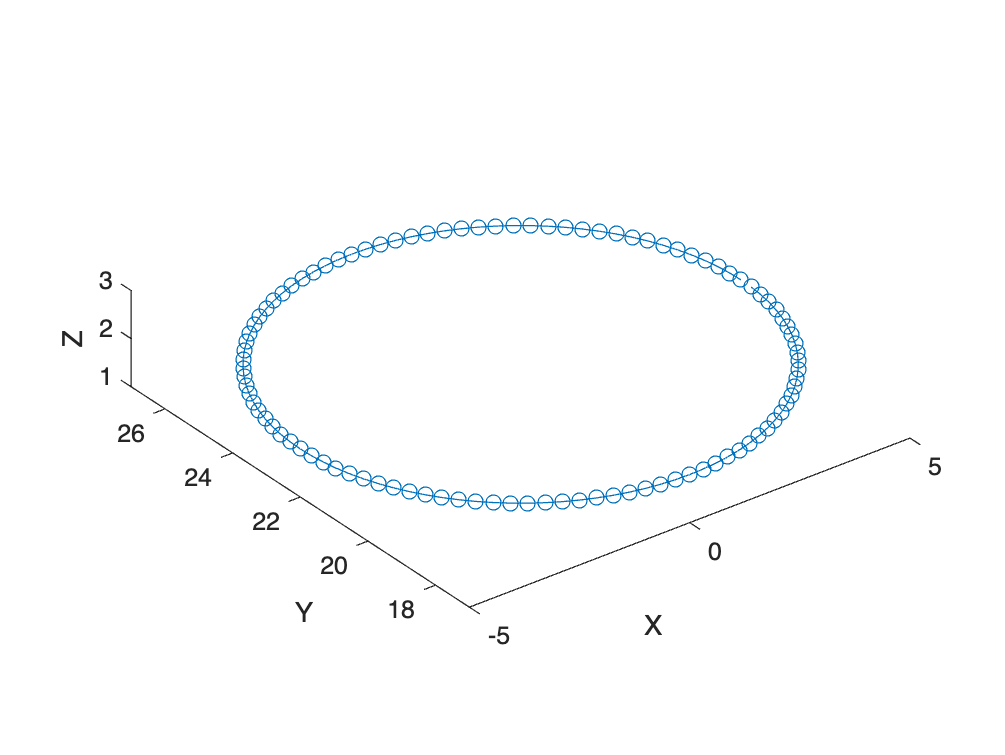

puntos_arcos_raya =     5.0000   22.0000    2.0000
    4.9901   22.3140    2.0000
    4.9606   22.6267    2.0000
    4.9114   22.9369    2.0000
    4.8429   23.2434    2.0000
    4.7553   23.5451    2.0000
    4.6489   23.8406    2.0000
    4.5241   24.1289    2.0000
    4.3815   24.4088    2.0000
    4.2216   24.6791    2.0000




%%workspace
%dibujarArcosEnAltura(100, 5, 0, pi, 20);
%%workspace v2
% puntos_arcos_raya = dibujarArcosSinRayita(100, 22, 0, pi, 3.5); 
%%circulo
puntos_arcos_raya = dibujarCirculoCentro(100, 5, 2, [0,22])

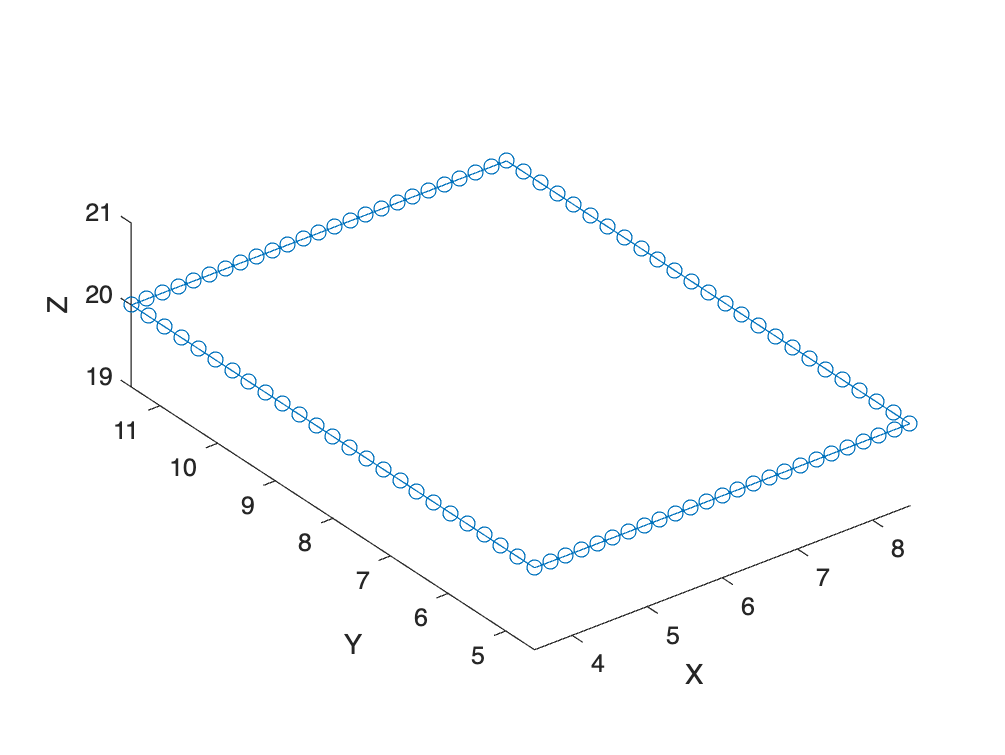

ans =     3.5000    4.5000   20.0000
    3.7083    4.5000   20.0000
    3.9167    4.5000   20.0000
    4.1250    4.5000   20.0000
    4.3333    4.5000   20.0000
    4.5417    4.5000   20.0000
    4.7500    4.5000   20.0000
    4.9583    4.5000   20.0000
    5.1667    4.5000   20.0000
    5.3750    4.5000   20.0000


%%rectangulo
dibujarRectanguloCentro(100, 5, 7, 20, [6,8])


% Carga el archivo .mat
%data = load('trayectoria_arcos_altura.mat');

% Accede a los datos almacenados en el archivo
matriz = data.puntos_arcos_altura; % Reemplaza 'nombre_de_la_variable'

% Obtiene el número de filas
N = size(matriz, 1);

% Crea un vector para almacenar los resultados
Vector3 = zeros(N, 3);

% Almacena los tres números de cada fila en el vector
for i = 1:N
   Vector3(i, :) = matriz(i, 1:3);
end

msg = rosmessage("px_msgs/pedroPascal")

msg =   ROS pedroPascal message with properties:

    MessageType: 'px_msgs/pedroPascal'
      Positions: [0×1 Vector3]

  Use showdetails to show the contents of the message



Points=[]


Points =

     []




for i=1:100
    vec3msg = rosmessage("geometry_msgs/Vector3")
    vec3msg.X = puntos_arcos_raya(i,2);
    vec3msg.Y = puntos_arcos_raya(i,1);
    vec3msg.Z = puntos_arcos_raya(i,3);
    Points=[Points,vec3msg]
end

vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 22
              Y: 5
              Z: 2

  Use showdetails to show the contents of the message


Points =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 22
              Y: 5
              Z: 2

  Use showdetails to show the contents of the message


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 22.3140
              Y: 4.9901
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×2 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 22.6267
              Y: 4.9606
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×3 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 22.9369
              Y: 4.9114
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×4 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 23.2434
              Y: 4.8429
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×5 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 23.5451
              Y: 4.7553
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×6 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 23.8406
              Y: 4.6489
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×7 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 24.1289
              Y: 4.5241
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×8 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 24.4088
              Y: 4.3815
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×9 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 24.6791
              Y: 4.2216
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×10 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 24.9389
              Y: 4.0451
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×11 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 25.1871
              Y: 3.8526
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×12 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 25.4227
              Y: 3.6448
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×13 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 25.6448
              Y: 3.4227
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×14 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 25.8526
              Y: 3.1871
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×15 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.0451
              Y: 2.9389
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×16 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.2216
              Y: 2.6791
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×17 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×18 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×19 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×20 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×21 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×22 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.9114
              Y: 0.9369
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×23 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.9606
              Y: 0.6267
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×24 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.9901
              Y: 0.3140
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×25 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 27
              Y: -8.0406e-16
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×26 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.9901
              Y: -0.3140
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×27 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.9606
              Y: -0.6267
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×28 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.9114
              Y: -0.9369
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×29 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.8429
              Y: -1.2434
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×30 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.7553
              Y: -1.5451
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×31 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.6489
              Y: -1.8406
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×32 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.5241
              Y: -2.1289
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×33 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.3815
              Y: -2.4088
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×34 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.2216
              Y: -2.6791
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×35 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 26.0451
              Y: -2.9389
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×36 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 25.8526
              Y: -3.1871
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×37 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 25.6448
              Y: -3.4227
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×38 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 25.4227
              Y: -3.6448
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×39 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 25.1871
              Y: -3.8526
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×40 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 24.9389
              Y: -4.0451
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×41 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 24.6791
              Y: -4.2216
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×42 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 24.4088
              Y: -4.3815
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×43 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 24.1289
              Y: -4.5241
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×44 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 23.8406
              Y: -4.6489
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×45 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 23.5451
              Y: -4.7553
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×46 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×47 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×48 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×49 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×50 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×51 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 21.6860
              Y: -4.9901
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×52 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 21.3733
              Y: -4.9606
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×53 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 21.0631
              Y: -4.9114
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×54 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 20.7566
              Y: -4.8429
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×55 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 20.4549
              Y: -4.7553
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×56 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 20.1594
              Y: -4.6489
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×57 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 19.8711
              Y: -4.5241
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×58 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 19.5912
              Y: -4.3815
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×59 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 19.3209
              Y: -4.2216
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×60 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 19.0611
              Y: -4.0451
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×61 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 18.8129
              Y: -3.8526
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×62 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 18.5773
              Y: -3.6448
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×63 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 18.3552
              Y: -3.4227
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×64 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 18.1474
              Y: -3.1871
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×65 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.9549
              Y: -2.9389
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×66 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.7784
              Y: -2.6791
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×67 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.6185
              Y: -2.4088
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×68 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.4759
              Y: -2.1289
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×69 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.3511
              Y: -1.8406
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×70 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.2447
              Y: -1.5451
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×71 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.1571
              Y: -1.2434
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×72 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.0886
              Y: -0.9369
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×73 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.0394
              Y: -0.6267
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×74 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.0099
              Y: -0.3140
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×75 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17
              Y: -9.1849e-16
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×76 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×77 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×78 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×79 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×80 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


Points =   1×81 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.3511
              Y: 1.8406
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×82 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.4759
              Y: 2.1289
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×83 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.6185
              Y: 2.4088
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×84 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.7784
              Y: 2.6791
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×85 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 17.9549
              Y: 2.9389
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×86 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 18.1474
              Y: 3.1871
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×87 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 18.3552
              Y: 3.4227
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×88 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 18.5773
              Y: 3.6448
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×89 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 18.8129
              Y: 3.8526
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×90 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 19.0611
              Y: 4.0451
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×91 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 19.3209
              Y: 4.2216
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×92 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 19.5912
              Y: 4.3815
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×93 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 19.8711
              Y: 4.5241
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×94 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 20.1594
              Y: 4.6489
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×95 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 20.4549
              Y: 4.7553
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×96 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 20.7566
              Y: 4.8429
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×97 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 21.0631
              Y: 4.9114
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×98 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 21.3733
              Y: 4.9606
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×99 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z


vec3msg =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 21.6860
              Y: 4.9901
              Z: 2

  Use showdetails to show the contents of the message


Points =   1×100 ROS Vector3 message array with properties:

    MessageType
    X
    Y
    Z



msg.Positions=Points

msg =   ROS pedroPascal message with properties:

    MessageType: 'px_msgs/pedroPascal'
      Positions: [100×1 Vector3]

  Use showdetails to show the contents of the message


rospublisher_1.send(msg)

function puntos_arcos_altura = dibujarArcosEnAltura(N, R, theta_start, theta_end, H)
    % Inicializar los puntos
    puntos_arcos_altura = zeros(N, 3);
    
    % Calcular el ángulo entre cada punto
    angulo = (theta_end - theta_start) / (N-1); %no c si dejar n-1 o n;
    
    % Generar los puntos para el primer arco
    for i = 1:N/2
        theta = theta_start + angulo * (i-1);
        puntos_arcos_altura(i, 1) = R * cos(theta);
        puntos_arcos_altura(i, 2) = R * sin(theta);
        puntos_arcos_altura(i, 3) = H;
    end
    
    % Generar los puntos para el segundo arco
    for i = N/2+1:N
        theta = theta_end - angulo * (i-N/2-1);
        puntos_arcos_altura(i, 1) = R * cos(theta);
        puntos_arcos_altura(i, 2) = -R * sin(theta);
        puntos_arcos_altura(i, 3) = H;
    end
    
    % Dibujar los arcos
    plot3(puntos_arcos_altura(:, 1), puntos_arcos_altura(:, 2), puntos_arcos_altura(:, 3), '-o');
    axis equal;
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    
    % Guardar los puntos en un archivo
    save('trayectoria_arcos_altura.mat', 'puntos_arcos_altura');
end

function puntos_arcos_raya = dibujarArcosSinRayita(N, R, theta_start, theta_end, H)
    % Inicializar los puntos
    puntos_arcos_raya = zeros(N, 3);
    
    % Calcular el ángulo entre cada punto
    angulo = (theta_end - theta_start) / (N - 1);
    
    % Generar los puntos para el primer arco
    for i = 1:N/2
        theta = theta_start + angulo * (i-1);
        puntos_arcos_raya(i, 1) = R * cos(theta);
        puntos_arcos_raya(i, 2) = R * sin(theta);
        puntos_arcos_raya(i, 3) = H;

        

    end

    
    
    % Generar los puntos para el segundo arco (espejo)
    for i = 1:N/2
        theta = theta_end - angulo * (i-1);
        puntos_arcos_raya(N/2+i, 1) = R * cos(theta);
        puntos_arcos_raya(N/2+i, 2) = -R * sin(theta);
        puntos_arcos_raya(N/2+i, 3) = H;
    end
    
    M = rotz(-45, 'deg'); 

    puntos_arcos_raya = (M * puntos_arcos_raya')'; 

    % Dibujar los arcos
    plot3(puntos_arcos_raya(1:N/2, 1), puntos_arcos_raya(1:N/2, 2), puntos_arcos_raya(1:N/2, 3), '-o');
    hold on;
    plot3(puntos_arcos_raya(N/2+1:end, 1), puntos_arcos_raya(N/2+1:end, 2), puntos_arcos_raya(N/2+1:end, 3), '-o');
    axis equal;
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    hold off;

     % Guardar los puntos en un archivo
    save('trayectoria_arcos_sin_rayita.mat', 'puntos_arcos_raya');
end

function puntos_circulo_centro = dibujarCirculoCentro(N, R, H, C)
    % Inicializar los puntos
    puntos_circulo_centro = zeros(N, 3);
    
    % Calcular el ángulo entre cada punto
    angulo = 2 * pi / N;
    
    % Calcular la posición del centro relativo al origen
    centro_x = C(1);
    centro_y = C(2);
    
    % Generar los puntos para el círculo
    for i = 1:N
        theta = angulo * (i-1);
        puntos_circulo_centro(i, 1) = R * cos(theta) + centro_x;
        puntos_circulo_centro(i, 2) = R * sin(theta) + centro_y;
        puntos_circulo_centro(i, 3) = H;
    end
    
    % Dibujar el círculo
    plot3(puntos_circulo_centro(:, 1), puntos_circulo_centro(:, 2), puntos_circulo_centro(:, 3), '-o');
    axis equal;
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    
    % Guardar los puntos en un archivo
    save('trayectoria_circulo_centro.mat', 'puntos_circulo_centro');
end



function puntos_rectangulo = dibujarRectanguloCentro(N, L, W, H, C)
    % Inicializar los puntos
    puntos_rectangulo = zeros(N, 3);
    
    % Calcular las coordenadas del centro relativas al origen
    centro_x = C(1);
    centro_y = C(2);
    
    % Calcular las mitades de la longitud y el ancho
    mitad_L = L / 2;
    mitad_W = W / 2;
    
    % Generar los puntos para el rectángulo
    puntos_rectangulo(1:N/4, 1) = linspace(-mitad_L, mitad_L, N/4) + centro_x;
    puntos_rectangulo(1:N/4, 2) = -mitad_W + centro_y;
    puntos_rectangulo(1:N/4, 3) = H;
    
    puntos_rectangulo(N/4+1:N/2, 1) = mitad_L + centro_x;
    puntos_rectangulo(N/4+1:N/2, 2) = linspace(-mitad_W, mitad_W, N/4) + centro_y;
    puntos_rectangulo(N/4+1:N/2, 3) = H;
    
    puntos_rectangulo(N/2+1:3*N/4, 1) = linspace(mitad_L, -mitad_L, N/4) + centro_x;
    puntos_rectangulo(N/2+1:3*N/4, 2) = mitad_W + centro_y;
    puntos_rectangulo(N/2+1:3*N/4, 3) = H;
    
    puntos_rectangulo(3*N/4+1:N, 1) = -mitad_L + centro_x;
    puntos_rectangulo(3*N/4+1:N, 2) = linspace(mitad_W, -mitad_W, N/4) + centro_y;
    puntos_rectangulo(3*N/4+1:N, 3) = H;
    
    % Dibujar el rectángulo
    plot3(puntos_rectangulo(:, 1), puntos_rectangulo(:, 2), puntos_rectangulo(:, 3), '-o');
    axis equal;
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    
    % Guardar los puntos en un archivo
    save('trayectoria_rectangulo_centro.mat', 'puntos_rectangulo');
end